clc; clear; close all;
format long g
%% ============================================================
% HEXAROTOR ALLOCATION INIT
%% ============================================================
N = 6;
R = 0.15;
c_f = 1e-4;
c_tau = 1e-4;

theta = (0:N-1) * 2*pi/N;

x = R*cos(theta);
y = R*sin(theta);

c_tau_i = [1;- 1; 1; 1; -1; 1] * c_tau;

%% Allocation matrix A
% w = [Fz; tau_x; tau_y; tau_z] = A*x
A = zeros(4,N);

for i = 1:N
    A(1,i) = c_f;
    A(2,i) = y(i) * c_f;
    A(3,i) = -x(i) * c_f;
    A(4,i) = c_tau_i(i);
end

fprintf('rank(A) = %d\n', rank(A));

rank(A) = 4



%% Kernel of A
K = null(A);

fprintf('dim ker(A) = %d\n', size(K,2));

dim ker(A) = 2



S = dec2bin(0:2^N-1) - '0';
S = 2*S - 1;
S = S.';

best_dist = inf;
best_s = [];
bA = [];

for j = 1:size(S,2)

    s = S(:,j);
    s_center = s / norm(s);

    p = K*(K.'*s_center);


    p = p / norm(p);

    if dot(p,s_center) < 0
        p = -p;
    end

    dist = norm(p - s_center);

    if dist < best_dist
        best_dist = dist;
        best_s = s;
        bA = p;
    end
end

a = K.'*bA;

a_perp = [-a(2); a(1)];

wA = K*a_perp;
wA = wA / norm(wA);

Caux = wA.';

Aaug = [A; Caux];

param.Aaug = Aaug;
param.bA = bA;
param.Cbar = 20;
param.layer_id= 6;


fprintf('Selected layer= %d\n', param.layer_id);

Selected layer= 0


fprintf('Selected C= %d\n', param.Cbar);

Selected C= 50


fprintf('bA = %d\n', param.bA);

bA = -4.082483e-01
bA = 4.082483e-01
bA = -4.082483e-01
bA = 4.082483e-01
bA = -4.082483e-01
bA = 4.082483e-01


fprintf('rank(Aaug) = %d\n', rank(Aaug));

rank(Aaug) = 5


disp(best_s.');

    -1     1    -1     1    -1     1



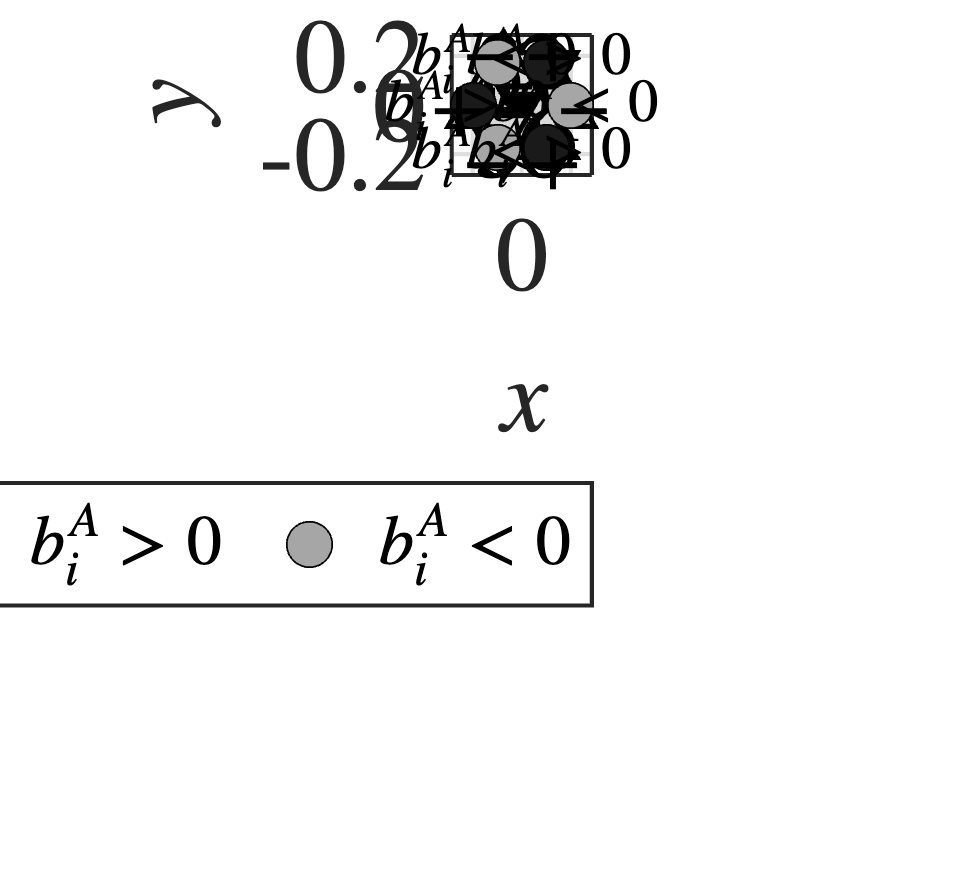

 plot_hexarotor_geometry(x,y,c_tau_i,bA,best_s,R,30)